## Grid-Topology Estimation for Supervisory Control of Microgrids

This script is made in order to estimate a Microgrid admitance matrix.

To do so, Matpower have been used ([https://matpower.org/.](https://matpower.org/.)). Matpower is an open source Matlab module made to simulate powerflow. This module as been used the simulate the network but also to access test cases

close all; clc; clear all;

# Part 1: Constants & Network definition

In this first section, the network will be defined from a Matpower test case. It will permit to have to real admitance matrix (benchmark), voltage and current data.

First, we'll set a random seed in order to have comparable experiments.

rng(11);

We load the data and we define the simulation setup to be used.

A test case can be chosen by filling the "loadcase" function

Noise can be added in the measurements trought** noise_v_sd **and **noise_i_sd**

define_constants;  % Matpower conventions
samples = 1000;
noise_v_sd = 0;
noise_i_sd = 0;
random_load_power_cv = 0.1;
mpc = loadcase('case57');

We define useful constants and we derive the impedence matrix **Y**.

The impedence matrix **Y** is displayed as a heatmap in order to vizualize the situation with one glance.

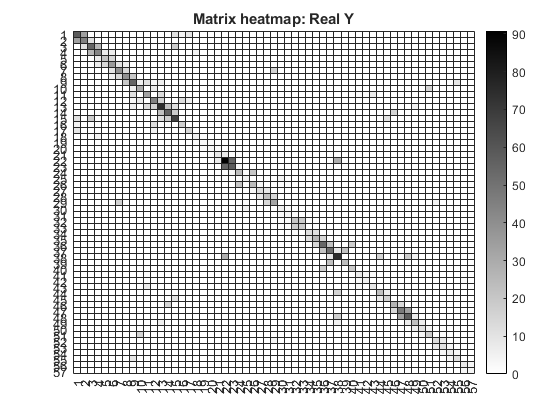

Y = full(makeYbus(mpc));
load_mask = mpc.bus(:, BUS_TYPE) == PQ;
controllable_mask = mpc.bus(:, BUS_TYPE) == PV;
n = size(mpc.bus, 1);
n_gen = size(mpc.gen, 1);
n_controllable = sum(controllable_mask);
n_load = n - n_gen;
matrix_heatmap(Y, 'Real Y');

We check that the admittance matrix is in Laplacian.

is_laplacian(Y)

ans = logical
   1


# Part 2: Grid simulation

In the second section, we will simulate the grid from the previously created admitance matrix. It will allow us the create the voltage and current data that will be used to estimate the admitance matrix. 

%simulate = true;
simulate = false;

if simulate
    load_avg_pd = mpc.bus(load_mask, PD);
    load_avg_qd = mpc.bus(load_mask, QD);
    bus_voltage = zeros(n, samples);
    load_pd = zeros(size(load_avg_pd, 1), samples);
    load_qd = zeros(size(load_avg_qd, 1), samples);
    for i = 1:samples
        mpc.bus(load_mask, PD) = normrnd(load_avg_pd, random_load_power_cv * abs(load_avg_pd));
        mpc.bus(load_mask, QD) = normrnd(load_avg_qd, random_load_power_cv * abs(load_avg_qd));
        res = runpf(mpc);
        bus_phase = res.bus(:, VA) * pi / 180;
        bus_magnitude = res.bus(:, VM);
        bus_voltage(:, i) = bus_magnitude .* (cos(bus_phase) + sqrt(-1) * sin(bus_phase));
        load_pd(:, i) = res.bus(load_mask, PD);
        load_qd(:, i) = res.bus(load_mask, QD);
    end
    save('save.mat','bus_voltage');
else
    bus_voltage = load('save.mat', 'bus_voltage').bus_voltage;
end

The voltage obtained with the simulation are theorical, but the application of the identification algorithm concerns measurement data. This is why white noise is applied to the measurements.

ev = normrnd(0, noise_v_sd, size(bus_voltage));
ei = normrnd(0, noise_i_sd, size(bus_voltage));
bus_current = Y * bus_voltage + ei;
bus_voltage = bus_voltage + ev;

Here is some exemple of bus voltage and current.

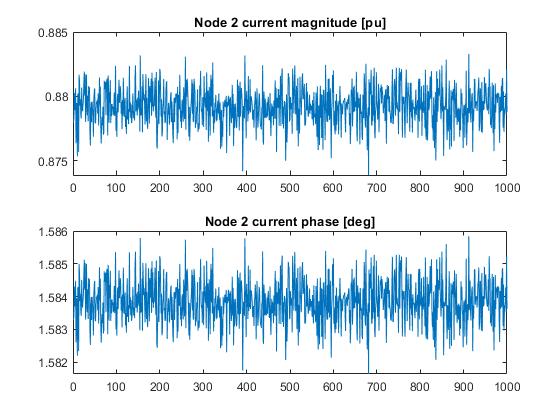

viz_node = 2;
viz_current = bus_current(viz_node, :);
viz_voltage = bus_voltage(viz_node, :);

figure()
subplot(2, 1, 1);
plot(1:samples, abs(viz_current));
title(sprintf('Node %d current magnitude [pu]', viz_node));
subplot(2, 1, 2);
plot(1:samples, angle(viz_current));
title(sprintf('Node %d current phase [deg]', viz_node));

# Part 3: Error metrics

We define the error metrics we are going to use to test the accuracy of the estimation algorithms. Define the error matrix $Y_e = \left |Y - \hat Y \right|$. We are going to use the following error metrics:

- Frobenius norm of $Y_e$

- Max norm of $Y_e$

Moreover, we will resort to an heatmap to see how the absoulte error in the estimation of the admittance matrix is distributed among the different elements.

# Part 4: Admitance matrix indentification benchmark

The goal of the project is to identify the admitance matrix of the grid with specific algorithms, thus it is interesting to compare it with traditional methods in order to compare the difference of performances but also to justify the use of more complex methods.

The benchmark chose is the ordinary least squared estimation.

Y_hat_ols = conj(bus_voltage' \ bus_current');

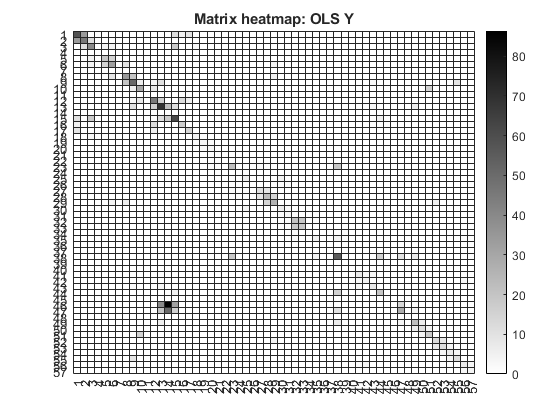

matrix_heatmap(Y_hat_ols, 'OLS Y');

With one glance, we are able to see that the OLS estimation performs very poorly.

Froebius norm for OLS is 260.8782
Max norm for OLS is 100.2015


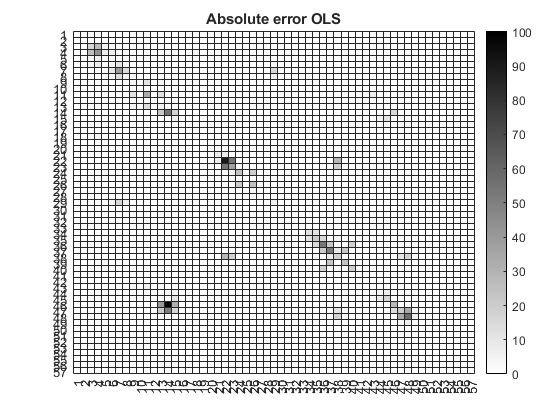

[ols_froeb_error, ols_max_error, chart] = error_metrics(Y, Y_hat_ols, 'OLS');

# Part 5: First least square estimation with low rank measures

There is $n^2$ parameters to estimate, those parameters correspond to a graph edges. Given this situation, there is a lot of interdependencies between nodal voltages. It implies that the voltages measurement matrix is low rank.

r = rank(bus_voltage)

r = 42

n-r

ans = 15

We notice that the rank is smaller than the number of bus, to solve this ill-posed problem the proposed algorithm uses a partitioning of the voltages matrix. In order to have one full rank partition.

[r, T] = full_rank_partioning(bus_voltage); % Algorithm 1 of the paper wasn't working but is found this matlab function
partitioned_v = T*bus_voltage;
partitioned_i = T*bus_current;
v1 = partitioned_v(1:end-r, :);
v2 = partitioned_v(end-r+1:end, :);
i1 = partitioned_i(1:end-r, :);
i2 = partitioned_i(end-r+1:end, :);

The proposed partion is made in a way that the r last row are the linearly independent rows **v2** and the first row are the others **v1**. The transformation matrix is **T**, such as $T*V=\left\lbrack \begin{array}{c}
\textrm{v1}\\
\textrm{v2}
\end{array}\right\rbrack$, $T*I=\left\lbrack \begin{array}{c}
\textrm{i1}\\
\textrm{i2}
\end{array}\right\rbrack$, $T^{\;} *Y*T^{-1\;\;} =\left\lbrack \begin{array}{cc}
Y_{1,1}  & Y_{1,2} \\
Y_{1,2}^T  & Y_{2,2} 
\end{array}\right\rbrack$

rank(v2) == r

ans = logical
   1


y11_size = n-r

y11_size = 15

y22_size = r

y22_size = 42

Since **v1** is in the row space of **v2** we can find **X** such as $\textrm{v1}=X*\textrm{v2}$

X = v1*pinv(v2);

The system can be rewritten as: $I_1 =\left(Y_{1,1} *X+Y_{1,2} \right)*v_2$, $I_2 =\left(Y_{1,2}^T *X+Y_{2,2} \right)*v_2$

By substitioning $Y_{1,2}$, We get $-X^T *Y_{1,1} *X+Y_{2,2} =C,\;C=I_2 *V_2^{\dagger } -{\left(V_2^{\dagger } \right)}^T *I_1^T *X$

C = i2*pinv(v2) - pinv(v2)'*i1'*X;

Vectorizing both sides of the equation yields to: $-\left(X^T \bigotimes X^T \right)*\mathrm{vec}\left(Y_{1,1} \right)+\mathrm{vec}\left(Y_{2,2} \right)=\mathrm{vec}\left(C\right)$

Whuch can be rewitten as: $\left\lbrack \begin{array}{cc}
-\left(X^T \bigotimes X^T \right) & I
\end{array}\right\rbrack *\left\lbrack \begin{array}{c}
\mathrm{vec}\left(Y_{1,1} \right)\\
\mathrm{vec}\left(Y_{2,2} \right)
\end{array}\right\rbrack =\mathrm{vec}\left(C\right)\;\Leftrightarrow A*x=b\;$

vec_c = reshape(C, [], 1);
b = vec_c;
A11 = -kron(X', X');
A22 = eye(y22_size^2, y22_size^2);
A12 = zeros(size(A11,1), size(A22,2));
A = [A11 A22];
x = A\b;

x1 = x(1:y11_size^2);
x2 = x(y11_size^2+1:end);

Y11_hat = reshape(x1, [y11_size, y11_size]);
Y22_hat = reshape(x2, [y22_size, y22_size]);

# USLESS BUT TO REMEMBER FOR RLS

We know that $Y_{1,1\;} \textrm{and}\;Y_{2,2}$ are symetric thus, we remove the redondant elements.

Let **D **being the transformation martix such as: $\textrm{vec}\left(Y_{i,i} \right)=D_i *\textrm{ve}\left(Y_{i,i} \right)\;$$\textrm{to}\;\textrm{remove}\;\textrm{redondant}\;\textrm{elements}\;\textrm{inducted}\;\textrm{with}\;\textrm{the}\;\textrm{symetry}$,

and **Q  **being the transformation martix such as: $\textrm{ve}\left(Y_{i,i} \right)=Q_i *x_i \;$to remove redondent elements induced with the Laplacian proporty.

D1 = duplication_matrix(y11_size);
D2 = duplication_matrix(y22_size);
Q1 = transformation_matrix(y11_size);
Q2 = transformation_matrix(y22_size);

We can rewrite our problem: $-\left(X^T \bigotimes X^T \right)*D_1 *x_1 +D_2 *\mathrm{x2}=\mathrm{vec}\left(C\right)$


$$\left\lbrack \begin{array}{cc}
-\left(X^T \bigotimes X^T \right)*D_1  & D_2 
\end{array}\right\rbrack *\left\lbrack \begin{array}{c}
\mathrm{x1}\\
\mathrm{x2}
\end{array}\right\rbrack =\mathrm{vec}\left(C\right)\;\iff A*x=b$$


% x1_size = (y11_size^2-y11_size)/2 + y11_size;
% x2_size = (y22_size^2-y22_size)/2 + y22_size;
% A = [-kron(X', X')*D1, D2];
% b = vec_c;

% x = A\b;
% 
% x1 = x(1:x1_size);
% x2 = x(x1_size+1:end);
% Y11_hat = reshape(D1*x1, [y11_size, y11_size]);
% Y22_hat = reshape(D2*x2, [y22_size, y22_size]);

# USLESS BUT TO REMEMBER FOR RLS

We recover the real $Y_{1,1} \;\textrm{and}\;Y_{2,2}$ to analyse the error

partitioned_Y = T*Y*inv(T);
Y11 = partitioned_Y(1:y11_size, 1:y11_size);
Y22 = partitioned_Y(y11_size+1:end, y11_size+1:end);

We can compute our first estimate using regular least squares

Froebius norm for Y11 OLS is 231.7578
Max norm for Y11 OLS is 105.3518


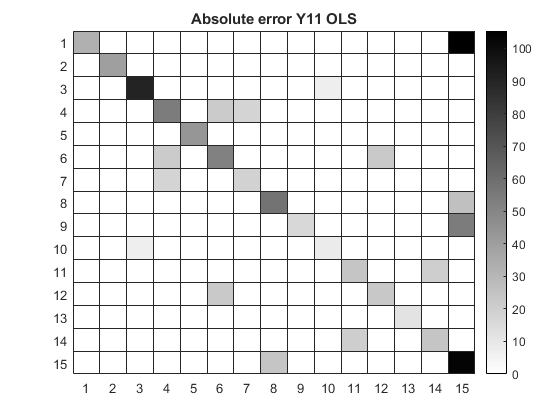


[ols_froeb_error, ols_max_error, chart] = error_metrics(Y11, Y11_hat, 'Y11 OLS');

Froebius norm for Y22 OLS is 128.213
Max norm for Y22 OLS is 65.4465


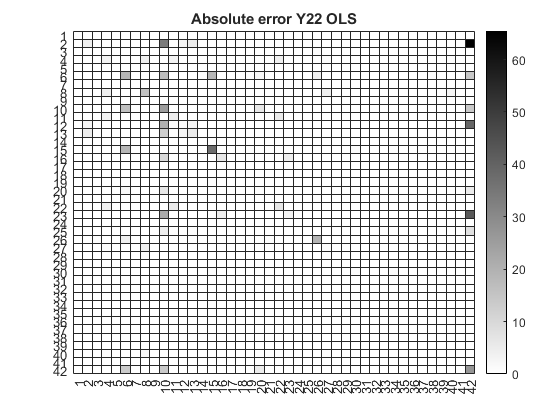

[ols_froeb_error, ols_max_error, chart] = error_metrics(Y22, Y22_hat, 'Y22 OLS');

Then we can estimate $Y_{1,2}$ from the previous equation $I_2 =\left(Y_{1,2}^T *X+Y_{2,2} \right)*V_2$


$$\begin{array}{l}
Y_{1,2}^T *X=I_2 *V_2^{\dagger } -Y_{2,2} \\
X^T *Y_{1,2} =I_2 *V_2^{\dagger } -Y_{2,2} \\
Y_{1,2} ={\left(X*X^T \right)}^{-1} *X*\left(I_2 *V_2^{\dagger } -Y_{2,2} \right)
\end{array}$$


Y12_hat = X'\(i2*pinv(v2)-Y22_hat);
Y_hat = inv(T)*[Y11_hat, Y12_hat; Y12_hat', Y22_hat];
matrix_heatmap(Y_hat_ols, 'OLS Y');

Froebius norm for OLS is 497.1024
Max norm for OLS is 143.394


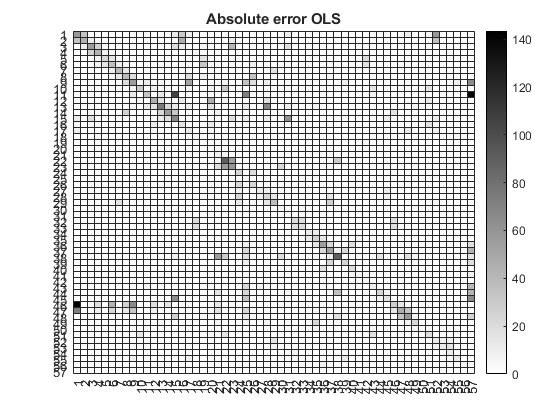

[ols_froeb_error, ols_max_error, chart] = error_metrics(Y, Y_hat, 'OLS');